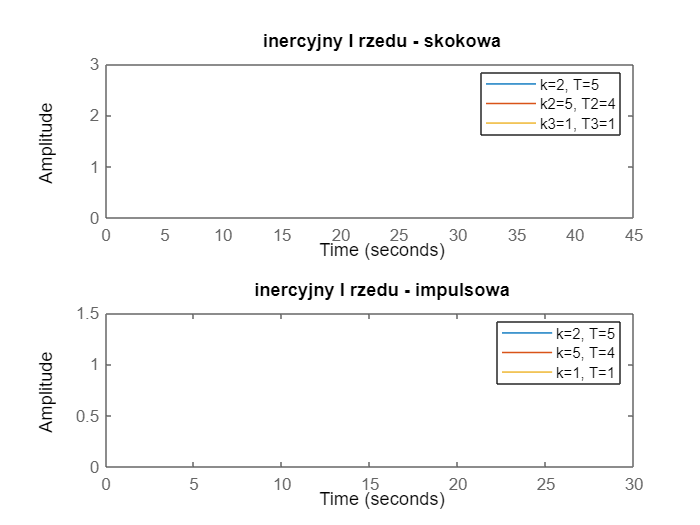

close all;
clear all;

k = 2;
T = 5;
k2 = 5;
T2 = 4;
k3 = 1;
T3 = 1;

licz = [0, k];
mian = [T, 1];

licz2 = [0, k2];
mian2 = [T2, 2];

licz1 = [0, k3];
mian1 = [T3, 1];

y1 = tf(licz, mian);
y2 = tf(licz1, mian1);
y3 = tf(licz2, mian2);

subplot(2,1,1)
step(y1, y2, y3)
title('inercyjny I rzedu - skokowa')
legend('k=2, T=5', 'k2=5, T2=4', 'k3=1, T3=1')

subplot(2,1,2)
impulse(y1, y2, y3);
title('inercyjny I rzedu - impulsowa')
legend('k=2, T=5', 'k=5, T=4', 'k=1, T=1')

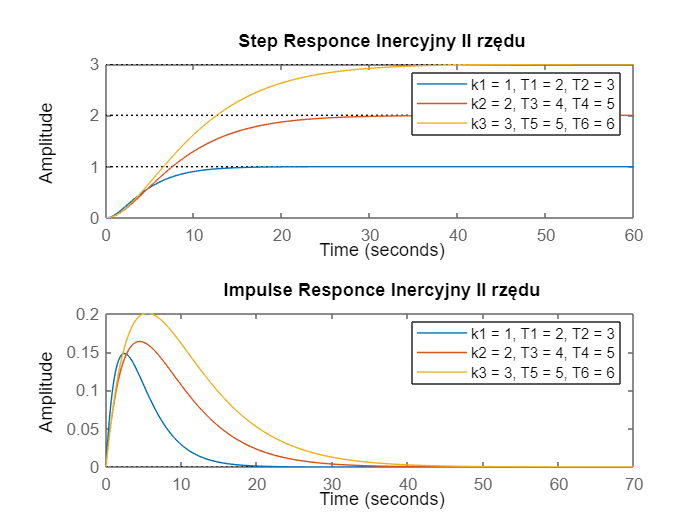

close all;
clear all;

k1 = 1;
T1 = 2;
T2 = 3;
licz = [0, 0, k1];
mian = [T1 * T2 ,T1 + T2 ,1];

k2 = 2;
T3 = 4;
T4 = 5;
licz1 = [0, 0, k2];
mian1 = [T3 * T4, T3 + T4, 1];

k3 = 3;
T5 = 5;
T6 = 6;
licz2 = [0, 0, k3];
mian2 = [T5 * T6, T5 + T6, 1];

y1 = tf(licz, mian);
y2 = tf(licz1, mian1);
y3 = tf(licz2, mian2);


subplot(2, 1, 1)
step(y1, y2, y3)
legend('k1 = 1, T1 = 2, T2 = 3','k2 = 2, T3 = 4, T4 = 5', 'k3 = 3, T5 = 5, T6 = 6');
title('Step Responce Inercyjny II rzędu')
subplot(2, 1, 2)
impulse(y1, y2, y3)
legend('k1 = 1, T1 = 2, T2 = 3','k2 = 2, T3 = 4, T4 = 5', 'k3 = 3, T5 = 5, T6 = 6');
title('Impulse Responce Inercyjny II rzędu')

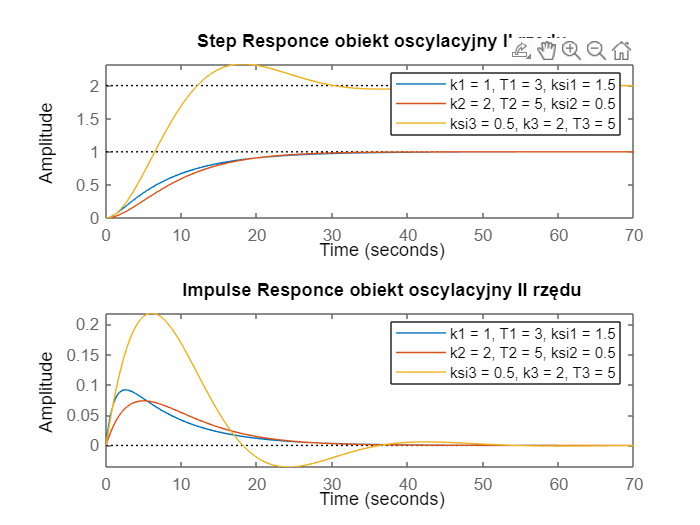

close all;
clear all;

ksi1 = 1.5;
k1 = 1;
T1 = 3;
licz1 = [0, 0, k1];
mian1 = [T1^2, 2 * ksi1 * T1, 1];

ksi2 = 1;
k2 = 1;
T2 = 5;
licz2 = [0, 0, k2];
mian2 = [T2^2, 2 * ksi2 * T2, 1];

ksi3 = 0.5;
k3 = 2;
T3 = 5;
licz3 = [0, 0, k3];
mian3 = [T3^2, 2 * ksi3 * T3, 1];

y1 = tf(licz1, mian1);
y2 = tf(licz2, mian2);
y3 = tf(licz3, mian3);
subplot(2, 1, 1)
step(y1, y2, y3)
legend('k1 = 1, T1 = 3, ksi1 = 1.5','k2 = 2, T2 = 5, ksi2 = 0.5', 'ksi3 = 0.5, k3 = 2, T3 = 5');
title('Step Responce obiekt oscylacyjny II rzędu')
subplot(2, 1, 2)
impulse(y1, y2, y3)
legend('k1 = 1, T1 = 3, ksi1 = 1.5','k2 = 2, T2 = 5, ksi2 = 0.5', 'ksi3 = 0.5, k3 = 2, T3 = 5');
title('Impulse Responce obiekt oscylacyjny II rzędu')

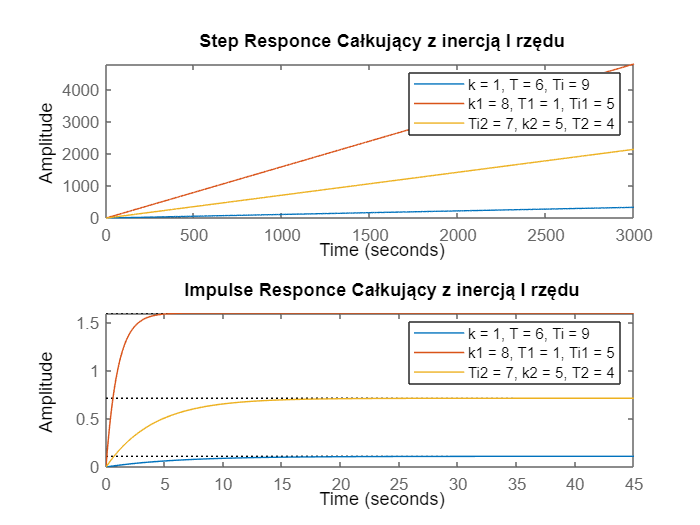

close all;
clear all;

Ti = 9;
T = 6;
k = 1;
T1 = 1;
k1 = 8;
Ti1 = 5;
Ti2 = 7;
k2 = 5;
T2 = 4;



licz = [0, 0, k];
mian = [T * Ti, Ti, 0];
licz1 = [0, 0, k1] ;
mian1 = [T1 * Ti1, Ti1 , 0];
licz2 = [0, 0, k2] ;
mian2 = [T2 * Ti2, Ti2 , 0];

y1 = tf(licz, mian);
y2 = tf(licz1, mian1);
y3 = tf(licz2, mian2);

subplot(2, 1, 1)
step(y1, y2, y3)
legend('k = 1, T = 6, Ti = 9','k1 = 8, T1 = 1, Ti1 = 5', 'Ti2 = 7, k2 = 5, T2 = 4');
title('Step Responce Całkujący z inercją I rzędu')

subplot(2, 1, 2)
impulse(y1, y2, y3)
legend('k = 1, T = 6, Ti = 9','k1 = 8, T1 = 1, Ti1 = 5', 'Ti2 = 7, k2 = 5, T2 = 4');
title('Impulse Responce Całkujący z inercją I rzędu')

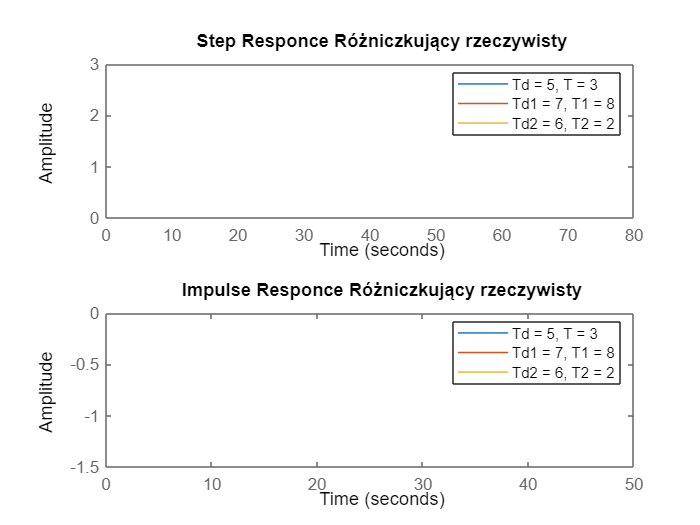

close all;
clear all;

Td = 5;
T = 3;
licz = [Td, 0];
mian = [T, 1];

y1 = tf(licz, mian);

Td1 = 7;
T1 = 8;
licz1 = [Td1, 0];
mian1 = [T1, 1];

y2 = tf(licz1, mian1);

Td2 = 6;
T2 = 2;
licz2 = [Td2, 0];
mian2 = [T2, 1];

y3 = tf(licz2, mian2);

subplot(2, 1, 1)
step(y1, y2, y3)
legend('Td = 5, T = 3','Td1 = 7, T1 = 8', 'Td2 = 6, T2 = 2');
title('Step Responce Różniczkujący rzeczywisty')
subplot(2, 1, 2)
impulse(y1, y2, y3)
legend('Td = 5, T = 3','Td1 = 7, T1 = 8', 'Td2 = 6, T2 = 2');
title('Impulse Responce Różniczkujący rzeczywisty')

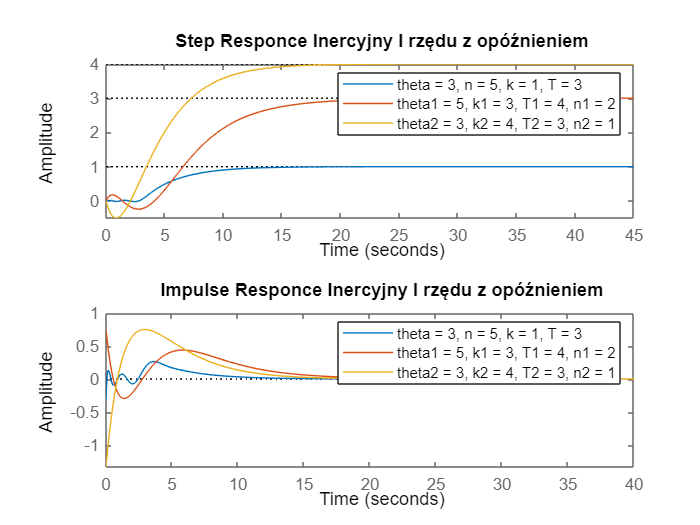

close all;
clear all;

theta = 3;
n = 5;
k = 1;
T = 3;

theta1 = 5;
k1 = 3;
T1 = 4;
n1 = 2;

theta2 = 3;
k2 = 4;
T2 = 3;
n2 = 1;

[licz_op, mian_op] = pade(theta, n);
licz_iner = [0, k];
mian_iner = [T, 1];
[licz, mian] = series(licz_op, mian_op, licz_iner, mian_iner);

y1 = tf(licz, mian);

[licz_op1, mian_op1] = pade(theta1, n1);
licz1_iner = [0, k1];
mian1_iner = [T1, 1];
[licz1, mian1] = series(licz_op1, mian_op1, licz1_iner, mian1_iner);

y2 = tf(licz1, mian1);

[licz_op2, mian_op2] = pade(theta2, n2);
licz2_iner = [0, k2];
mian2_iner = [T2, 1];
[licz2, mian2] = series(licz_op2, mian_op2, licz2_iner, mian2_iner);

y3 = tf(licz2, mian2);

subplot(2, 1, 1)
step(y1, y2, y3)
legend('theta = 3, n = 5, k = 1, T = 3', 'theta1 = 5, k1 = 3, T1 = 4, n1 = 2', 'theta2 = 3, k2 = 4, T2 = 3, n2 = 1');
title('Step Responce Inercyjny I rzędu z opóźnieniem')

subplot(2, 1, 2)
impulse(y1, y2, y3)
legend('theta = 3, n = 5, k = 1, T = 3', 'theta1 = 5, k1 = 3, T1 = 4, n1 = 2', 'theta2 = 3, k2 = 4, T2 = 3, n2 = 1');
title('Impulse Responce Inercyjny I rzędu z opóźnieniem')